clear
clc
close all

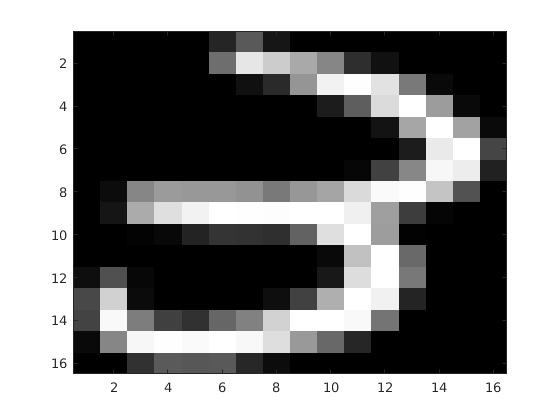

% Loading data
load threes -ascii

% Visualising image
colormap('gray');
imagesc(reshape(threes(1,:),16,16),[0,1]);

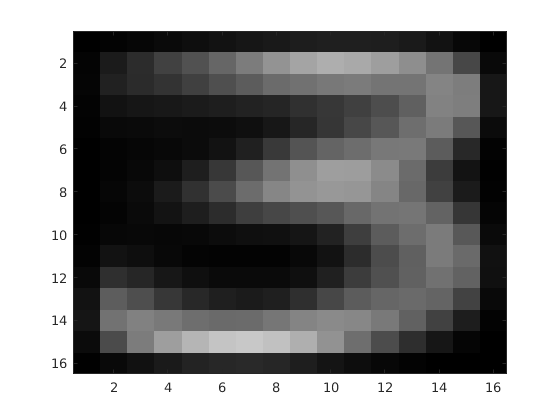


% Calculating and visualising the mean '3'
mean3 = mean(threes);
imagesc(reshape(mean3(1,:),16,16),[0,1]);

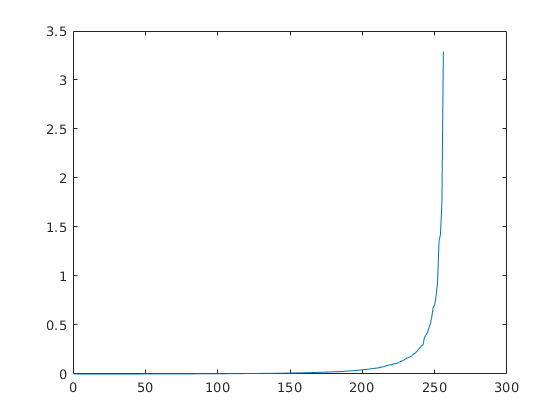

% Transpose data for now
data = threes';

%Calculate the mean
mean_vector = mean(data,2);

%Zero mean the dataset by subtracting the mean
zero_data = data - mean_vector;

% Computing the covariance matrix
covariance = cov(zero_data');

% Computing eigenvectors and eigenvalues of covariance matrix
[vectors,values] = eig(covariance);
sum_total_values = sum(diag(values));

% Plotting eigenvalues
plot(diag(values));

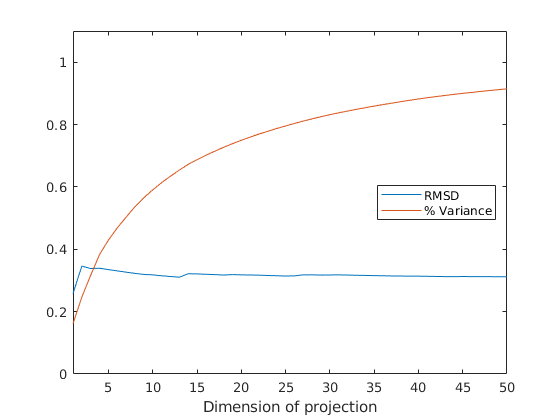

%Initialise errors and eigenvalue-percentages arrays
errors = zeros(1,50);
var_subs = zeros(1,50);

for q=1:50
    %Compute the reduced eigenvalues and eigenvactors of the covariance matrix
    [E, reduced_values] = eigs(covariance, q);
    sum_reduced_values = sum(diag(reduced_values));
    
    %Compute the percentage of variance captured by subspace
    var_sub = sum_reduced_values/sum_total_values;
    var_subs(1,q) = var_sub;
    
    %Compute transpose of reduced eigenvectors
    E_T = E';
    
    %Reduce the dataset by multipling with E_T
    reduced_data = E_T*data;
    
    %Generate reconstructed dataset from reduced dataset
    new_data_zerod = E*reduced_data;
    new_data = new_data_zerod + mean_vector;
    
    % Transposing back for plotting
    reconstructed_threes = new_data';
    
    %Estimate the error
    RMSD = sqrt(mean(mean((threes-reconstructed_threes).^2)));
    errors(1,q) = RMSD;
end

%Plotting RMSD for different q-values
plot(errors);
hold on;
plot(var_subs);
xlabel('Dimension of projection')
xlim([1 q]);
ylim([0 1.1]);
legend({'RMSD','% Variance'},'Location','east')
hold off;